% loaded file
inputFilename = 'mini-me_short.wav'; 
targetFs = 10000;  

% resample in case original Fs is different from target
% maybe I will chage this later
[y_signal, fs_y_signal] = audioread(inputFilename);
if fs_y_signal ~= targetFs
    y_signal = resample(y_signal, targetFs, fs_y_signal); 
end

% time vector for plotting
t_signal = (0:length(y_signal)-1) / targetFs;

**Frequency Content of Original Signal**

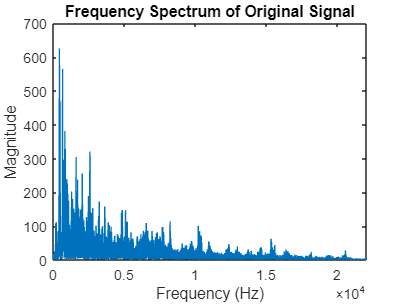

Y = fft(y_signal);
f = (0:length(Y)-1) * (fs_y_signal / length(Y));  % Frequency vector
figure;
plot(f, abs(Y));
title('Frequency Spectrum of Original Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 fs_y_signal/2]);  % Limit to Nyquist frequency

**Original Signal in Time Domain**

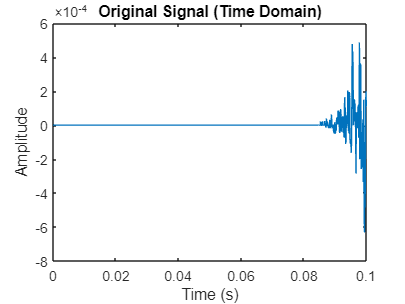

figure;
plot(t_signal, y_signal);
title('Original Signal (Time Domain)');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 0.1]);  %  time window 

We set the filter order, cutoff frequencies (1,000 Hz and 4,000 Hz), and the sampling frequency. 

filterOrder = 4; 
cutoffFrequencies = [1000 4000]; 
fs = targetFs;  

normalize cutoff frequencies - Nyquist 

normalizedCutoff = cutoffFrequencies / (fs / 2);

this designs a **Butterworth bandpass filter** and returns the filter coefficients. this is build in function from Matlab

[b, a] = butter(filterOrder, normalizedCutoff, 'bandpass'); 

**FIR filter to the signal and the plot**

filteredSignal = builtin('filter', b, a, y_signal);

% amplitude range check for y-axis limits
minValFiltered = min(filteredSignal);
maxValFiltered = max(filteredSignal);
fprintf('Filtered Signal Min: %f, Filtered Signal Max: %f\n', minValFiltered, maxValFiltered);

Filtered Signal Min: -0.377832, Filtered Signal Max: 0.431719


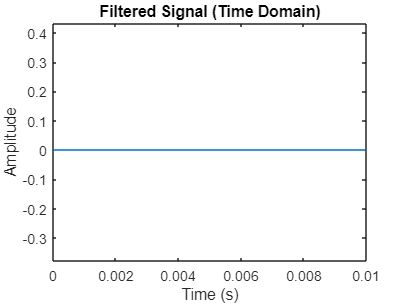


% plot filtered (time fomain)
figure;
plot(t_signal, filteredSignal);
title('Filtered Signal (Time Domain)');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 0.01]);  % time limit
ylim([minValFiltered, maxValFiltered]); % Dynamic y-axis limits (filtered signal range)

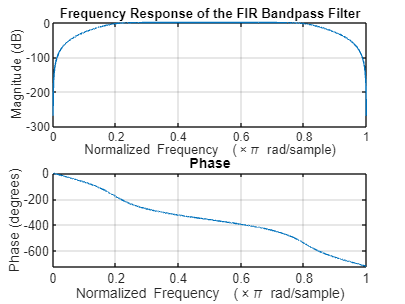


% freq response of the FIR Filter
figure;
freqz(b, a, fs);
title('Frequency Response of the FIR Bandpass Filter');

We can also save the coefficients, and we can easily reload and apply this exact filter to new data without re-running the filter design code

coefficientsTable = table(b', a', 'VariableNames', {'Numerator', 'Denominator'});
writetable(coefficientsTable, 'fir_filter_coefficients.txt');

**Play**

sound(filteredSignal, fs)